# HIGH PASS FILTER USING BLT

fs = 5000;
t = 5;
n =(0:1/fs:t)

n =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


x = 2*sin(2*pi*5*n);

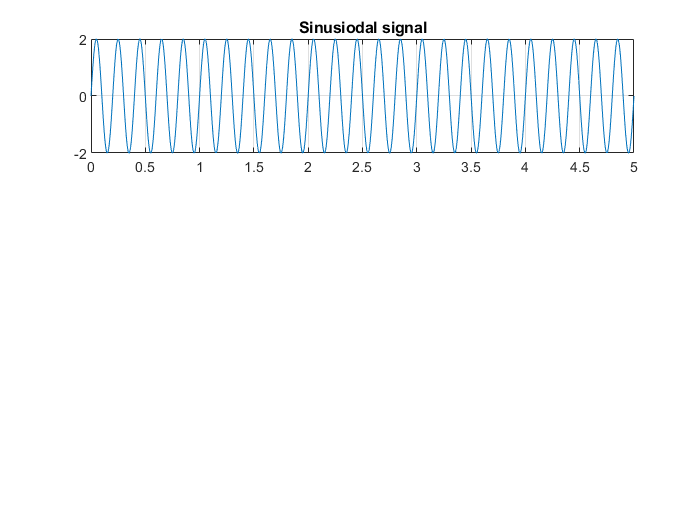

%Plot sine wave
subplot(3,1,1)
plot(n,x)
grid on
title('Sinusiodal signal');


% Aditive White Gaussian noisy signal
z=awgn(x,1)          

z =     0.2836    2.1704    0.7787    0.7439    1.4278   -0.2107    1.1226   -0.0386    0.6245    0.2475   -0.1283   -0.7496    0.1515    0.2653    0.2172    0.2117    0.0086    0.7276    0.8904    0.9926    0.2313   -0.1919    1.7065    0.1382   -0.0763   -0.3620    0.2170    0.3903    0.0011    0.2829   -0.7236   -0.1988   -0.6071    0.4432    1.2337   -0.0703   -0.3481   -0.4742    0.9627    0.6954    0.6233    1.5110   -0.8204    1.7492   -0.8676    1.4808    0.7791    0.1109    1.1829    1.4072


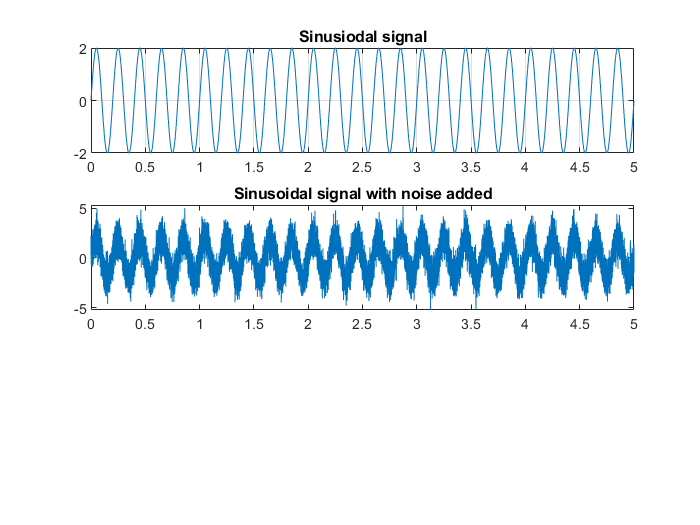

subplot(3,1,2)
plot(n,z)
title('Sinusoidal signal with noise added');

%IIR Butterworth LPF filter Design
o=1                 % order of the filter

o = 1